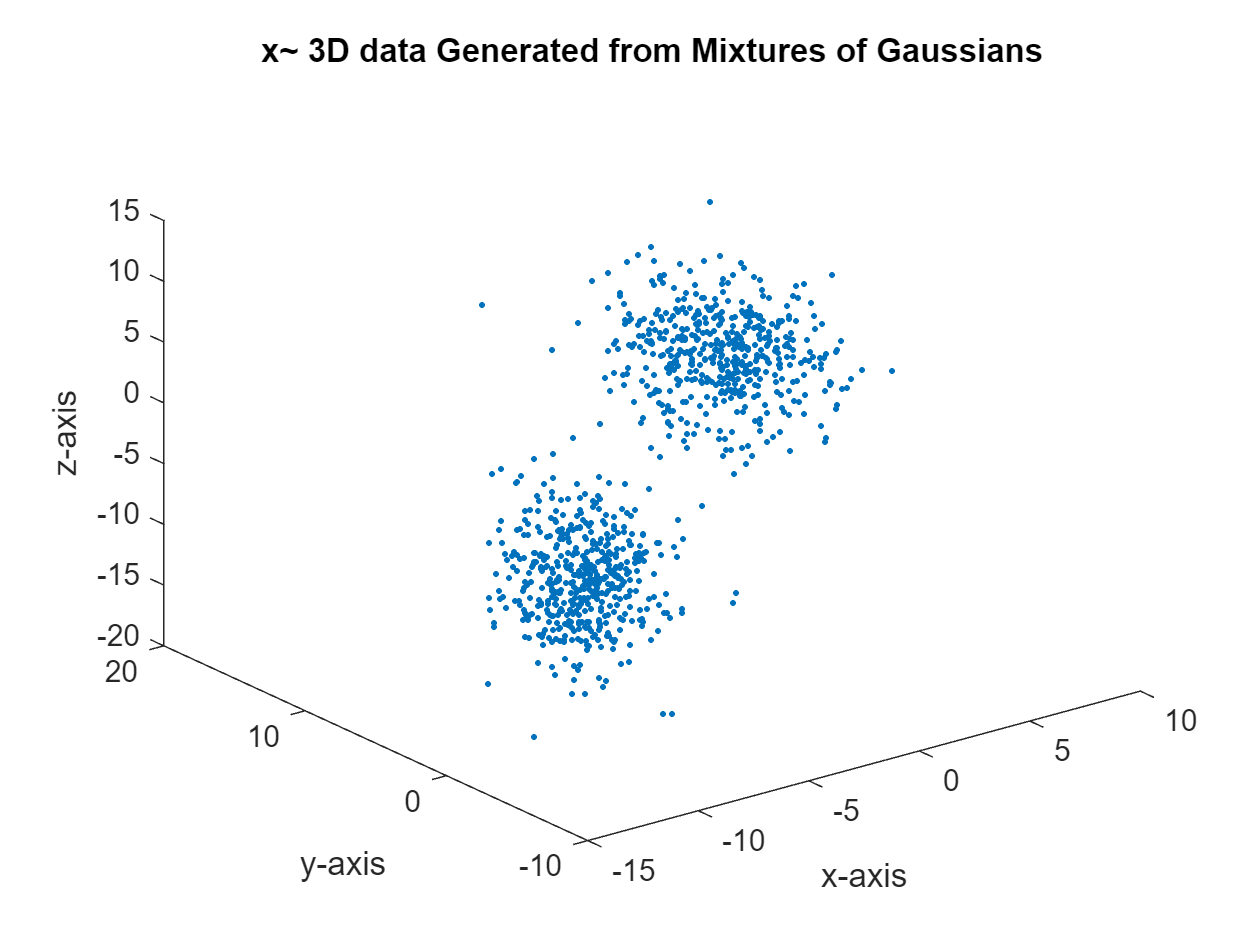

clc, clear all, close all,
%%% This example is an illustration of the application of PCA on data
%%% generated using Gaussian mixture models or uniform mixuture models with
%%% different dimensionalities.
%%% PDF parameters are selected first, then data is generated from a
%%% mixture of PDFs. Principal componenents are later generated using data,
%%% then data is projected on the Principal components and plotted.

%%% PCA applied to data from a Gaussian Mixture PDF %%%
%% generate data  from an arbitrary GMM
N=1000; %specify number of samples generated
mu=[1 -10 3; 4 -2 10; 5 -5 0];% 3 normal distributions means of x, y and z axis
sigma(:,:,1)=[2 -.5 -.4; -.5 6 -.2; -.4 -.2 10 ]; %1st normal distribution covariance
sigma(:,:,2)=[2 .5 .6; .5 5 .8;.6 .8 10]; % 2nd normal distribution covariance
sigma(:,:,3)=[4 .5 -.9; .5 7 .4; -.9 .4 12]; %3rd normal distribution covariance
%store parameters in a structure
gmmParameters.meanVectors=mu;
gmmParameters.covMatrices=sigma;
gmmParameters.priors=[0.2 0.5 0.3];%the likelihood of each distribution to be selected
%generate 3D matrix from 3 mixtures of Gaussians
xGMM =generateDataFromGMM_OG(N,gmmParameters,1); 

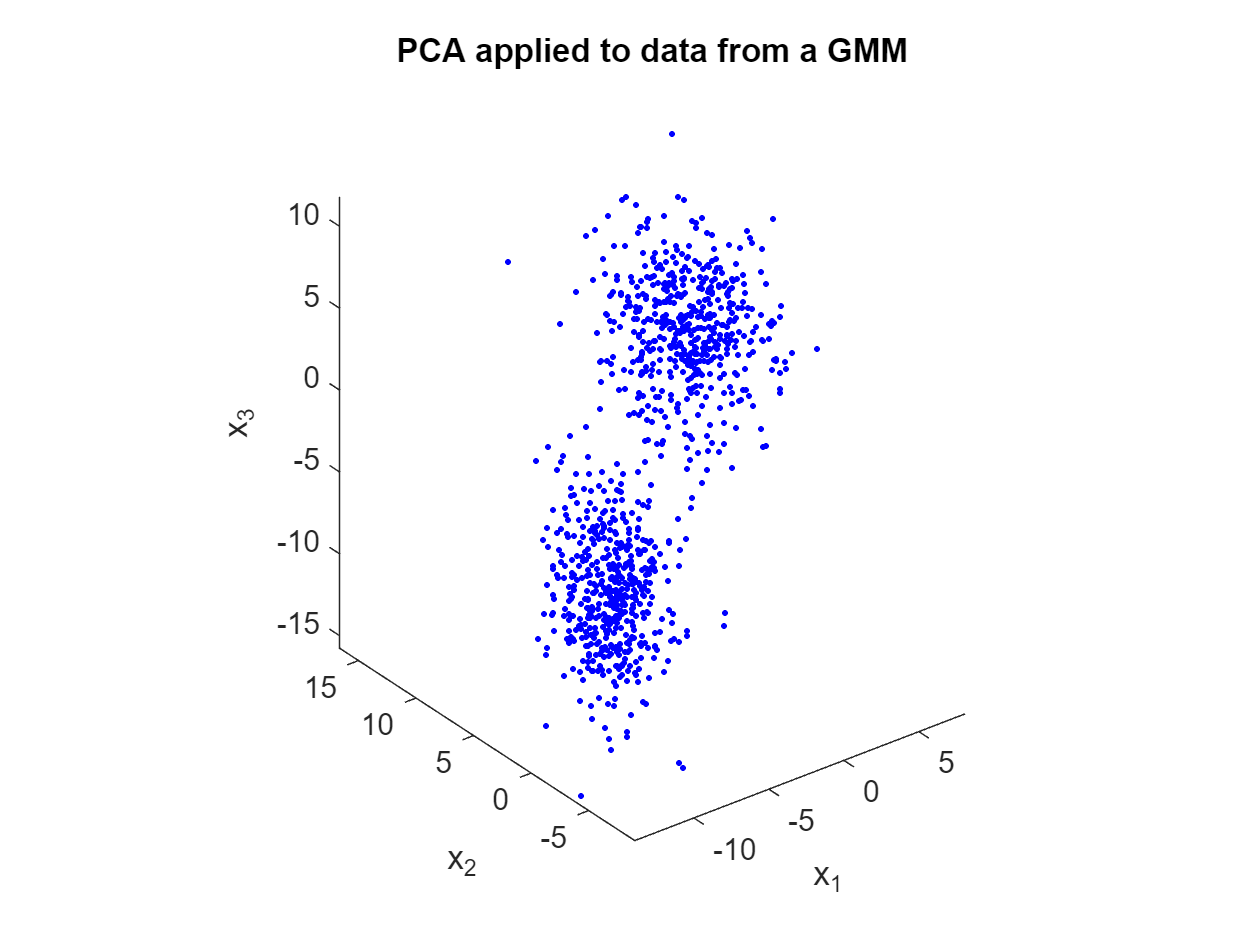

%% determine the principal components of data from GMM
% determine PCA transformation matrix Q and PCs
[Q,D,xzm,yzm]=performPCA(xGMM);
% Project the data on the principal components 
yGMM = Q'*xzm+mean(xGMM,2); % y has PCs shifted to the mean of x
%% plot 
% plot projected data vs original data
figure(), plot3(xGMM(1,:),xGMM(2,:),xGMM(3,:),'.b'); axis equal,
xlabel('x_1'), ylabel('x_2'),zlabel('x_3')
title('PCA applied to data from a GMM'),

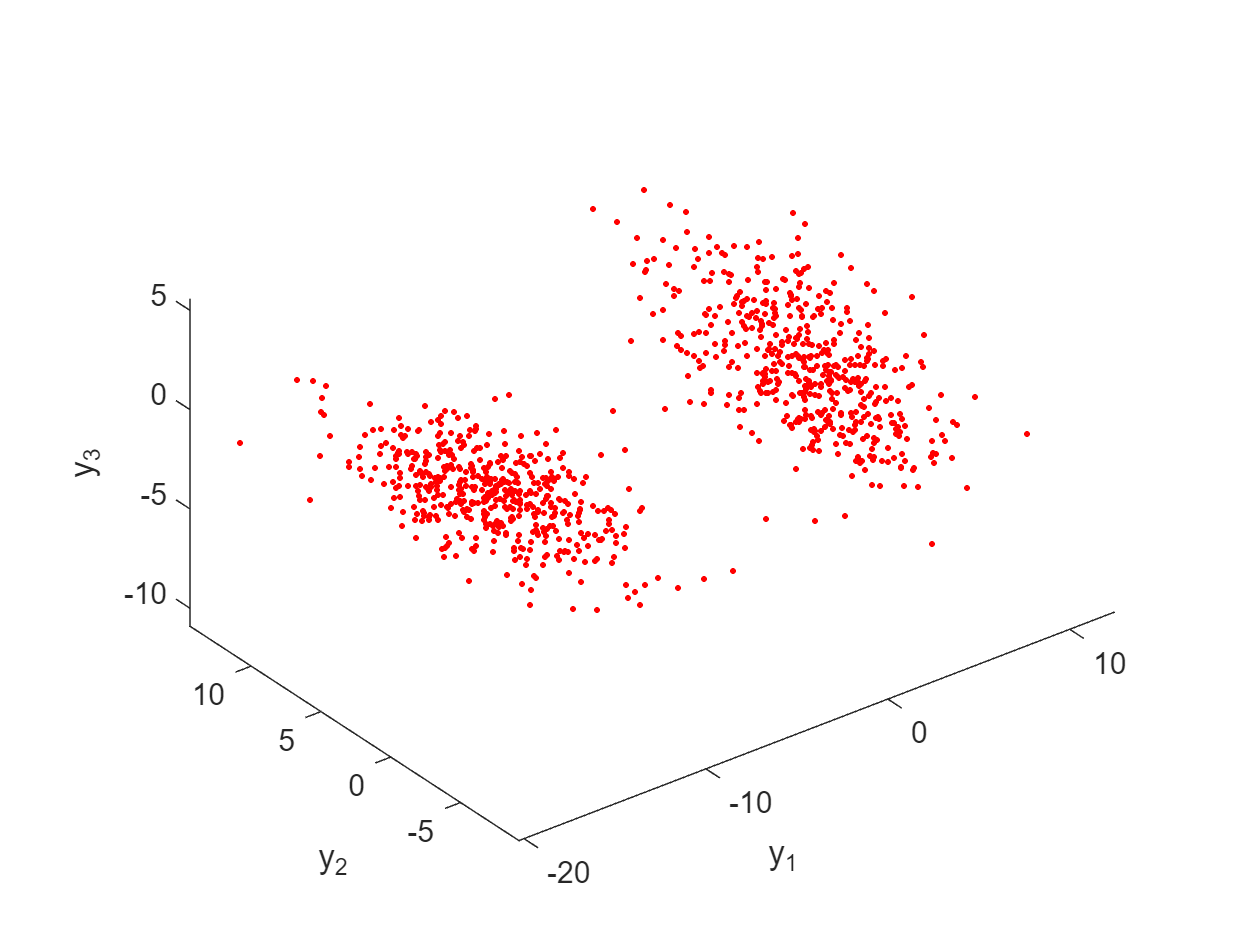

figure(),plot3(yGMM(1,:),yGMM(2,:),yGMM(3,:),'.r'); axis equal,
xlabel('y_1'), ylabel('y_2'),zlabel('y_3')

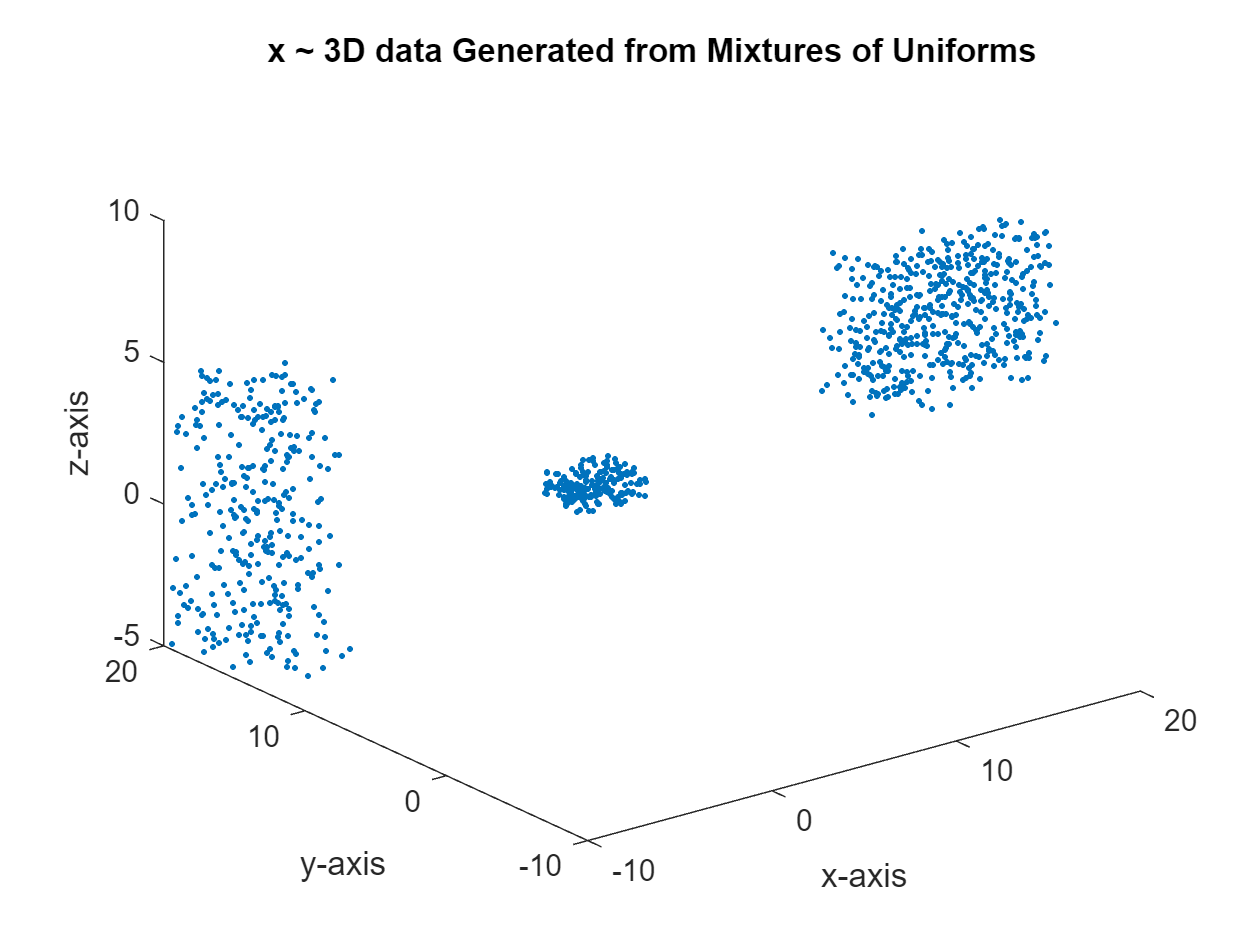

%%% PCA applied to data from a Uniform Mixture PDF %%%
%% generate data from an arbitrary uniform mixture PDF
N=1000; %specify number of samples generated
ummParameters.priors=[0.2 0.3 0.5];%the likelihood of each distribution to be selected
ummParameters.a=[1 -10 10 ; 5 13 -5; 1 -5  5];%uniform distributions lower endpoints for x, y and z axis
ummParameters.b=[5 -5 20;  8 20 0;2 5  10] ; %uniform distributions higher endpoints for x,y and z axis
%generate 3D matrix from 3 mixtures of Uniforms
xUMM =generateDataFromUMM(N,ummParameters,1); 

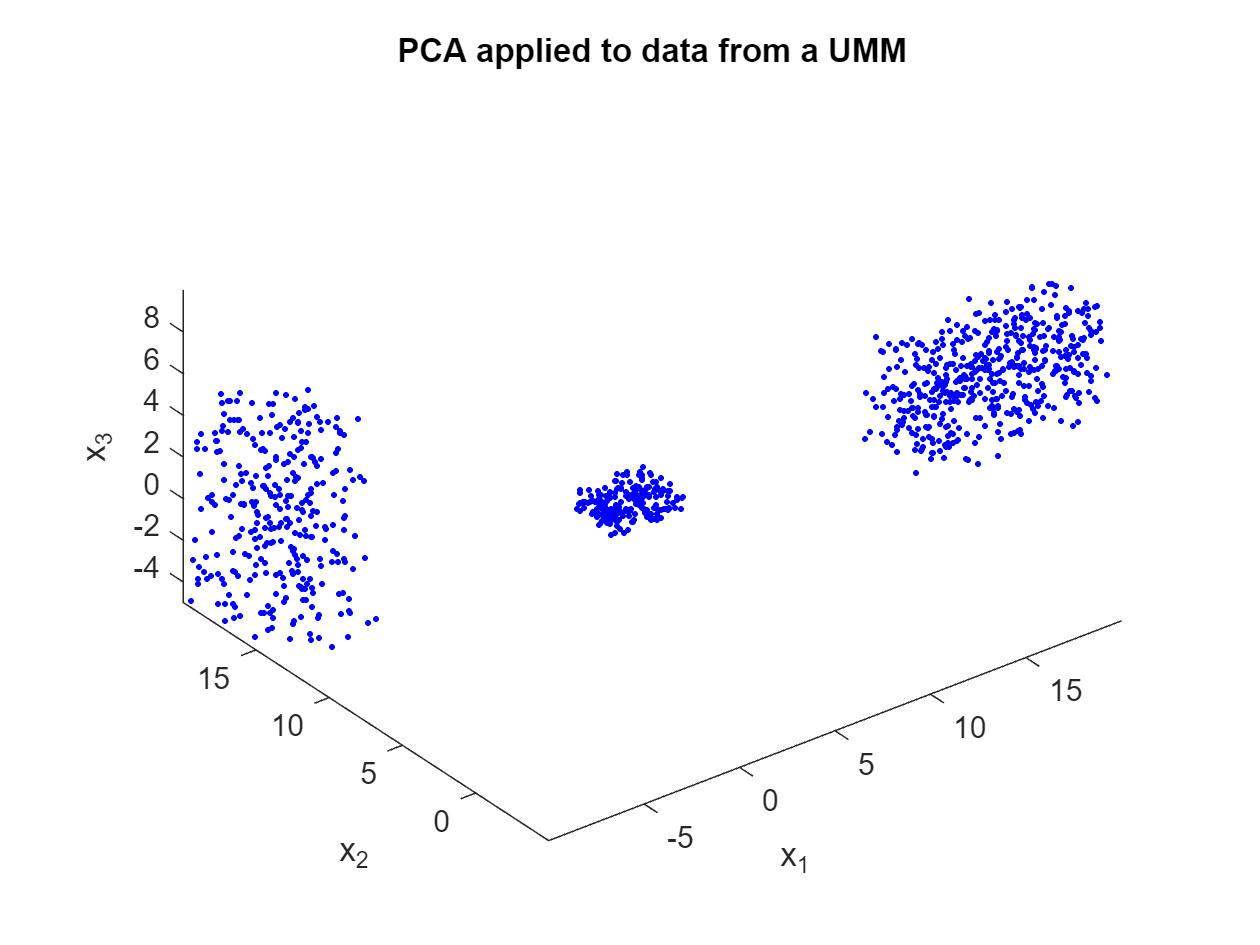

%% determine the principal components 
%determine PCA transformation matrix Q and PCs
[Q,D,xzm,yzm]=performPCA(xUMM);
% Project the data on the principal components 
yUMM = Q'*xzm+mean(xUMM,2); % y has PCs shifted to the mean of x

%% plot 
%plot projected data vs original data
figure(),plot3(xUMM(1,:),xUMM(2,:),xUMM(3,:),'.b'); axis equal,
xlabel('x_1'), ylabel('x_2'),zlabel('x_3'),
title('PCA applied to data from a UMM'),

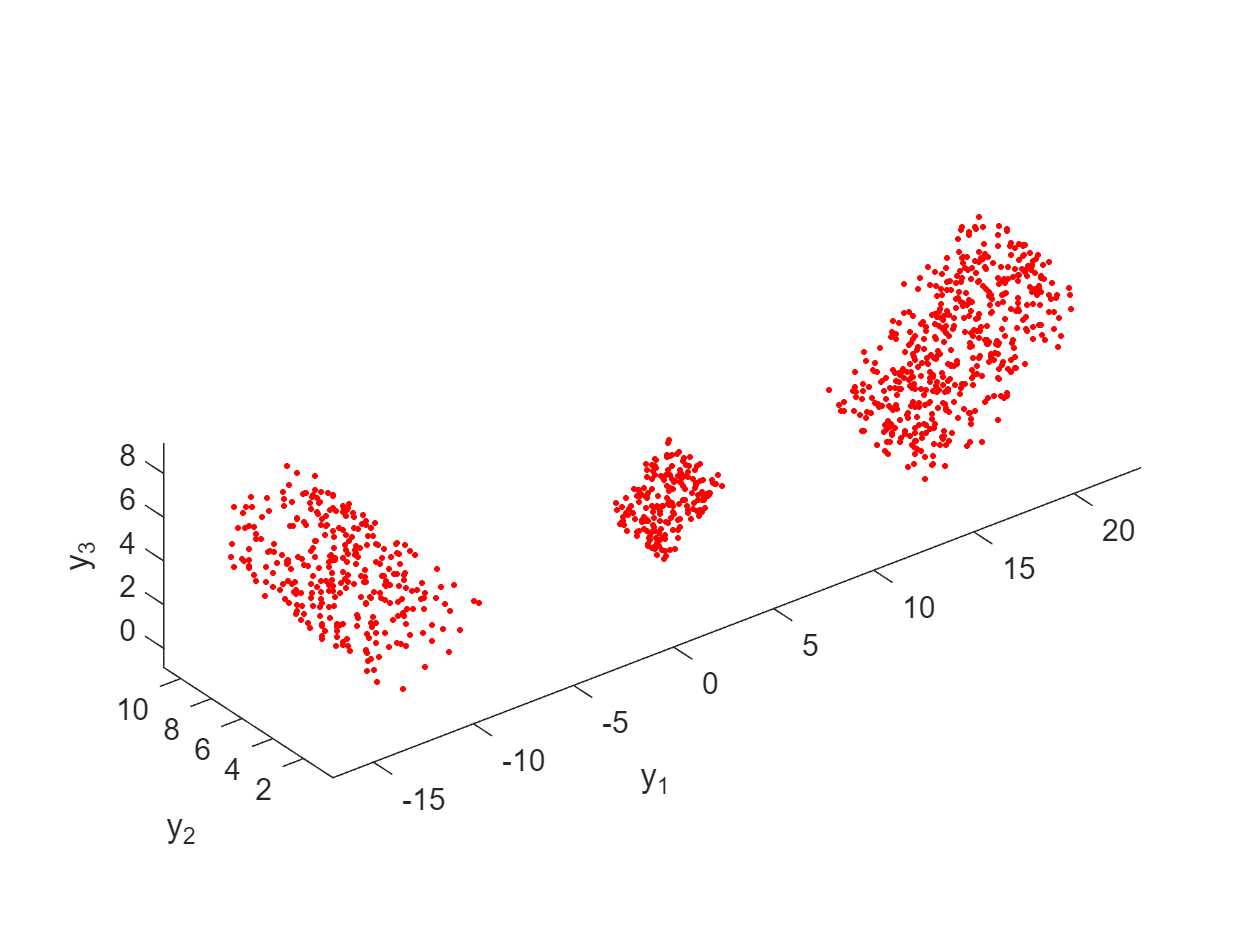

figure(),plot3(yUMM(1,:),yUMM(2,:),yUMM(3,:),'.r'); axis equal,
xlabel('y_1'), ylabel('y_2'),zlabel('y_3')